### **Método das Secantes**


$$x^{k+1} = \frac{x^{k-1}f(x^{k})-x^{k}f(x^{k-1})}{f(x^{k})- f(x^{k-1})$$


Vamos encontrar o zero da função $f(x) = -0.5x^{2}+2.5x+4.5$ no intervalo de $[-2.5,0]$utilizando o método das Secantes, com  chute inicial $x^{0} = -2$ e $x^{1} = 0$ erro relativo igual ou menor que $10^{-4}$.

**Graficamente, **

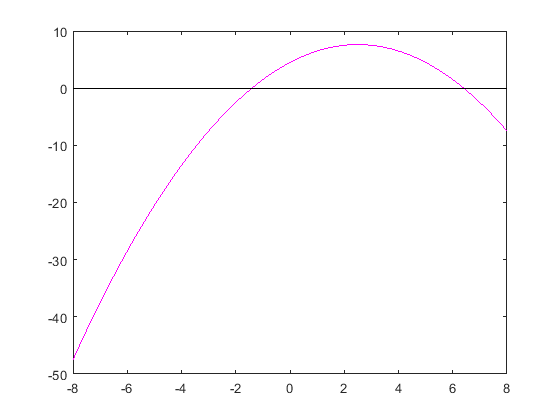

x= -8:0.01:8;
y = fun(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off

**Implementação do Newton-Raphson:**

format long
%Chute inicial
x0 = -2;
x1 = 0;
fx0 = fun(x0);
tol = 10^-4;
k = 0;
er = abs(x1-x0)/abs(x1);
while(er > tol)
    x = (x0*fun(x1)-x1*fun(x0))/(fun(x1)-fun(x0)); %atualizando o zero da função usando o metodo das secantes
    x0 = x1;
    x1 = x;
    er = abs(x1-x0)/abs(x1);%calculando erro relativo
    fx0 = fun(x0);
    k = k+1;
    xk(k,:) = x0;
    fk(k,:) = fun(fx0);
    erk(k,:) = er;
end
[xk,fk, erk]

ans =                    0   5.625000000000000   1.000000000000000
  -1.285714285714286   5.542534360683048   0.102040816326531
  -1.431818181818182   4.233036953962758   0.019296740994854
  -1.404711821623896   4.504030687034336   0.000292934752085
  -1.405123431107836   4.500013734750611   0.000001001277504


**Definindo as funções que serão utilizadas:**

function f1 = fun(x)
    f1 = -0.5*x.^2 +2.5*x + 4.5;
end
